# Final Project

**Yi-Chong Jiang, Aidan Strong, Eugene Hsue & Oscar Cheng**

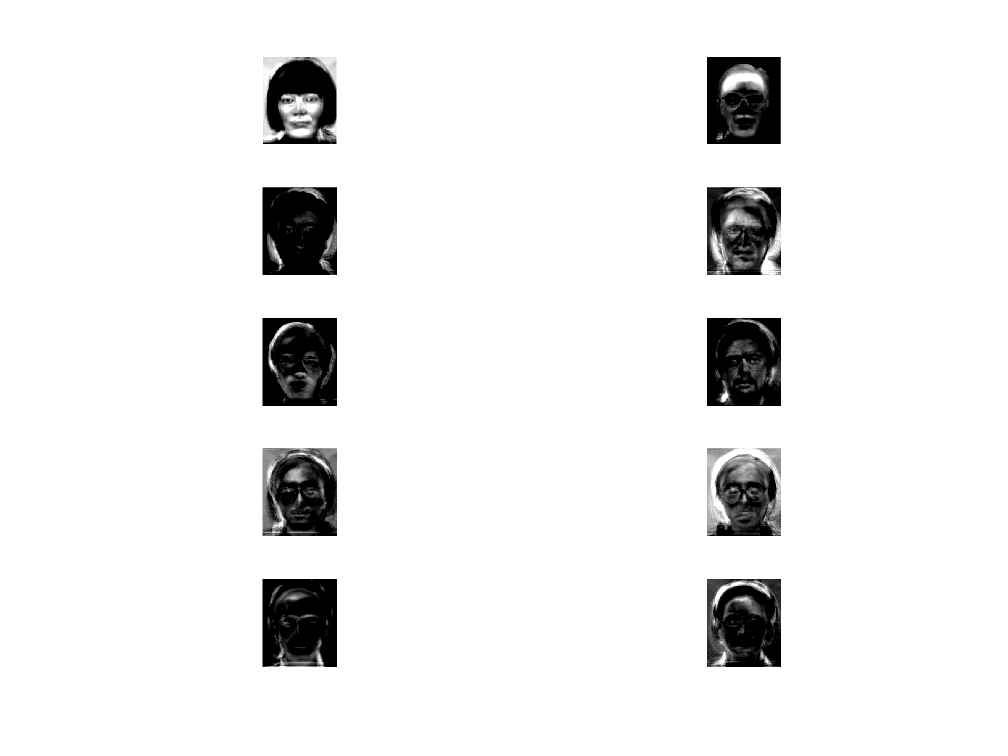

clear;clc;close all;

% Step one, load up all the face images
Files=dir('Faces');

% Getting the dimensions of the face
test = imread('Faces/subject01.centerlight.pgm');
M = size(test,1);
N = size(test,2);

% Every directory has "." and ".." so we need to disregard those
count = length(Files)-2;

% Setup the average face vector
averageFace = zeros(M*N,1,'double');

% Our total matrix of M*N vectors of face
totalFaceMatrix = zeros(M*N,count);

for k=3:length(Files)
   name = Files(k).name;

   % Read the face, turn it into a double
   face = double(imread("Faces/"+name))/255;

   % Turn it into a column
   columnFace = reshape(face,[],1);

   % Construct the large face matrix by setting the whole column
   totalFaceMatrix(:,k) = columnFace;

   % Add it to the average face
   averageFace = averageFace + columnFace;
end


% Compute average face
averageFace = averageFace / count;

% Find the covariance matrix
covariance = transpose(totalFaceMatrix)*totalFaceMatrix;

% Find the eigenvalues (returns diagonal matrix D of generalized eigenvalues and full matrix V whose columns are the corresponding right eigenvectors,  so that A*V = B*V*D.)
[eigenVectors,eigenValues] = eig(covariance);
% Sort the eigenvalues, keep track of how we sorted them 
[sortedEigenvalues,ind] = sort(diag(eigenValues));
sortedEigenvectors = eigenVectors(:,ind);

% Get the K-Largest Eigenvalues
KLargestCount = 10;

for e=1: KLargestCount

    eigenface = sortedEigenvectors(:,count-e);

    finalEigenface = zeros(M,N,'double');

    for k=3:length(Files)

        name = Files(k).name;
        % Reread the file 
        face = double(imread("Faces/"+name))/255;
    
        % Add a linear combination
        finalEigenface = finalEigenface + eigenface(k-2)*face;

    end
    subplot(5,2,e)
    imshow(finalEigenface)
end